
% Pacheck, Nicholas
% 1-D Beamforming Patterns
clc, clear, clearvars
% Define signal parameters
freq = 10e6;
omega = 2*pi*freq;
speed0light = 3e8;
wavelen = speed0light/freq;

% Define array parameters
spacing = wavelen/2;
nAntennas = 20;
array_length = spacing*nAntennas;

% Define Antenna Element coordinates
x_coords = linspace(0, array_length, nAntennas);

% Define azimuthal vector span
azimSpan = linspace(-90, 90, 180);

% Define Element Factor
EF = 3;
%Define AOA
AOA = 26

AOA = 26


% Define Element Pattern
EP = (cosd(azimSpan)).^(EF/2); % reduces side lobe grating

% Define Array factor
AF = 0

AF = 0

for i = 1:nAntennas

    % Compute phase shift
    phase_shift = (2*pi/wavelen)*x_coords(i)*(sind(azimSpan) - sind(AOA));

    % Compute steering weight
    steer = exp(j*phase_shift);

    % SUM
    AF = AF + steer;

end

plot(azimSpan, AF)

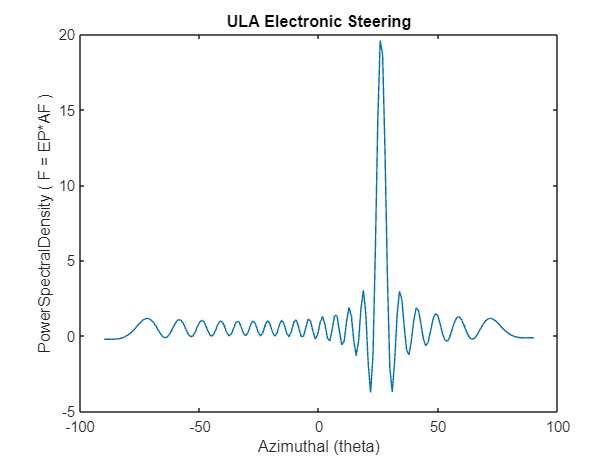

title("ULA Electronic Steering")
xlabel("Azimuthal (theta)")
ylabel("PowerSpectralDensity ( F = EP*AF )")